# Image Processing with MATLAB

This lecture is partly adapted from MATLAB online tutorial and [MATLAB examples](https://www.mathworks.com/help/examples.html).

## Image Processing Toolbox

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/image.html)

Image Processing Toolbox™ provides a comprehensive set of reference-standard algorithms and workflow apps for image processing, analysis, visualization, and algorithm development. 

It provides tools and algorithms for:

- image segmentation

- image enhancement

- noise reduction

- geometric transformations

- image registration

- 3D image processing

- ... ...

**Install Toolbox:**

Add-Ons --> Get Add-Ons --> search for the toolbox --> install

* Image data used in this lecture comes from [Stanford Dogs Dataset](http://vision.stanford.edu/aditya86/ImageNetDogs/).

### Import and Display Images

Load and display an image

I1 = imread("data/01.jpg");
imshow(I1)

Load another image

I2 = imread("data/02.jpg");
imshow(I2)
size(I1),size(I2)

Resize and display two images together.

`imresize`'s default interpolation method is `bicubic`. Bicubic interpolation can produce pixel values outside the original range.

I1 = imresize(I1, [400,500],"Method","bilinear");
I2 = imresize(I2, [400,500],"Method","bilinear");
imshowpair(I1,I2,"montage")

Trim the white border for the second image.

close_to_white = I2(:,:,1)>240 & I2(:,:,2)>240 & I2(:,:,3)>240;
is_wht_c = sum(close_to_white,1)>size(close_to_white,1)*.5;
is_wht_r = sum(close_to_white,2)>size(close_to_white,2)*.5;

row1 = find(diff(is_wht_r)==-1)+1;
row2 = find(diff(is_wht_r)==1);
col1 = find(diff(is_wht_c)==-1)+1;
col2 = find(diff(is_wht_c)==1);
croppedI2 = I2(row1:row2, col1:col2, :);
imshow(croppedI2)
size(croppedI2) 

I2 = imresize(croppedI2, [400,500],"Method","bilinear");
imshowpair(I1,I2,"montage")

Display an image with alternating rectangular regions from each

imshowpair(I1,I2,"checkerboard")

close all; clear; clc

### Grayscale and Color Images

Extract Color Planes and Intensity Values

I = imread("data/03.jpg");
[R,G,B] = imsplit(I);
% or
% R = I(:,:,1);
% G = I(:,:,2);
% B = I(:,:,3);
montage({I,R,G,B},'Size',[2 2])

Convert to grascale image

gs = rgb2gray(I);
imshow(gs)

Save image

imwrite(gs,"img_gs.jpg")

#### Rotate and compare images 

`J ``= imrotate(I,angle,method,bbox)` rotates image `I` using the interpolation method specified by `method`. The `bbox` argument to define the size of the output image.

I_rot = imrotate(I,5,'bicubic','crop');
imshowpair(I,I_rot,'montage')

Display the difference

imshowpair(I,I_rot,'diff')

Display a blended overlay

imshowpair(I,I_rot,'blend','Scaling','joint')

### Contrast and Intensity Histograms

When analyzing a set of images, normalizing the brightness can be an important preprocessing step. An **intensity histogram** separates pixels into bins based on their intensity values. Dark images, for example, have many pixels binned in the low end of the histogram. Bright regions have pixels binned at the high end of the histogram.

gs = rgb2gray(I);
imhist(gs)

Multiple techniques for **grayscale image contrast enhancement**:

- `imadjust` increases the contrast of the image by mapping the values of the input intensity image to new values such that, by default, 1% of the data is saturated at low and high intensities of the input data.

- `histeq` performs histogram equalization. It enhances the contrast of images by transforming the values in an intensity image so that the histogram of the output image approximately matches a specified histogram (uniform distribution by default).

- `adapthisteq` performs contrast-limited adaptive histogram equalization (CLANE). Unlike `histeq`, it operates on small data regions (tiles) rather than the entire image. Each tile's contrast is enhanced so that the histogram of each output region approximately matches the specified histogram (uniform distribution by default). The contrast enhancement can be limited in order to avoid amplifying the noise which might be present in the image.

gsAdj1 = imadjust(gs);
gsAdj2 = histeq(gs);
gsAdj3 = adapthisteq(gs);
montage({gs,gsAdj1,gsAdj2,gsAdj3})

Display intensity historgram for the adjusted image

imhist(gsAdj2)

### **Thresholding Intensity Values**

Threshold the intensity values of a grayscale image with automated threshold selection process by using the `imbinarize` function, which calculates the "best" threshold for the image.

BW = imbinarize(gsAdj1,"adaptive");
BW_default = imbinarize(gsAdj1);
imshowpair(BW_default,BW,"montage")

Choose the foreground to be dark 

BW = imbinarize(gsAdj1,"adaptive","ForegroundPolarity","dark");
imshowpair(gsAdj1,BW,"montage")

close all

### Working with binary images

I = imread("data/04.jpg");
gs = rgb2gray(I);
BW = imbinarize(gs,"adaptive","ForegroundPolarity","dark");
imshowpair(gs,BW,"montage")
figure("Position",[1,1,500,200])
subplot(1,2,1)
plot(sum(BW,2)) % sum across each row
subplot(1,2,2)
plot(sum(BW,1)) % sum across each column

close all

### **Filtering Noise**

Images taken in low light often become noisy due to the increase in camera sensitivity required to capture the image. To reduce the impact of this noise on the binary image, preprocess the image with an averaging filter.

H = fspecial("average",3);
gssmooth = imfilter(gs,H,"replicate");
BWsmooth = imbinarize(gssmooth,"adaptive","ForegroundPolarity","dark");
imshowpair(BW,BWsmooth,"montage")

Try a motion-blur filter for fun.

H_motion = fspecial('motion', 20, 0);
I_motion = imfilter(I,H_motion,"replicate");
imshowpair(I,I_motion,"montage")

close all

### **Background Subtraction**

**Remove the Background. **

A `strel` object represents a flat morphological *structuring element*, which is an essential part of morphological dilation and erosion operations. The following figure illustrates a flat structuring element.

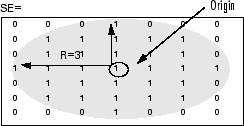

I = imread("data/02.jpg");
gs = rgb2gray(I);
SE = strel("disk",40)

Ibg = imclose(gs,SE);
imshow(Ibg)

gsSub = Ibg-gs;
imshow(gsSub)

BWsub = ~imbinarize(gsSub);
imshowpair(I,BWsub,"montage")

close all; clear; clc

### Image Saturation

**Adjust the saturation of a color image by converting the image to the HSV color space.**

Convert the image to the HSV color space.

I = imread("data/01.jpg");
HSV = rgb2hsv(I);

Process the HSV image and increases the saturation of the image by multiplying the S channel by a scale factor.

[h,s,v] = imsplit(HSV);
saturationFactor = 1.8;
s_sat = s*saturationFactor;
HSV_sat = cat(3,h,s_sat,v);

Convert the processed HSV image back to the RGB color space. 

I_sat = hsv2rgb(HSV_sat);
imshowpair(I,I_sat,"Montage")

### Reduce Noise in Image Gradients

I = imread("data/02.jpg");
gs = rgb2gray(I);

Simulate noise: add some Gaussian noise

gs_noisy = imnoise(gs,'gaussian',0,0.05);
imshowpair(gs,gs_noisy,"Montage")

Compute the magnitude of the gradient.

sobelGradient = imgradient(gs_noisy);
imshow(sobelGradient,[])
title('Sobel Gradient Magnitude')

The effect of noise can be minimized by smoothing before gradient computation. 

Smooth the image using a **Gaussian smoothing filter** before computing image gradients. Use the `imgaussfilt` function to smooth the image. The standard deviation of the Gaussian filter varies the extent of smoothing. Since smoothing is taken care of by Gaussian filtering, the central or intermediate differencing gradient operators can be used.

sigma = 2; % 5
gs_smooth = imgaussfilt(gs_noisy,sigma);
smoothGradient = imgradient(gs_smooth);
imshow(smoothGradient,[])
title('Smoothed Gradient Magnitude')

close all; clear; clc

## Computer Vision Toolbox

[https://www.mathworks.com/products/computer-vision.html](https://www.mathworks.com/products/computer-vision.html)

Computer Vision Toolbox™ provides algorithms, functions, and apps for designing and testing computer vision, 3D vision, and video processing systems.

It provides tools and algorithms for:

- object detection and tracking

- feature detection, extraction, and matching

- automating calibration workflows for single, stereo, and fisheye cameras

- visual and point cloud SLAM, stereo vision, structure from motion, and point cloud processing

- ... ...

More exmaples using Computer Vision Toolbox can be found here: [Computer Vision Toolbox — Examples](https://www.mathworks.com/help/vision/examples.html?category=index&exampleproduct=all&s_tid=CRUX_lftnav).

### Demo: Semantic Segmentation Using Dilated Convolutions 

This demo is taken from MATLAB examples. The dataset contains 32-by-32 triangle images. 

% load image data
dataFolder = fullfile(toolboxdir('vision'),'visiondata','triangleImages');
imageFolderTrain = fullfile(dataFolder,'trainingImages');
labelFolderTrain = fullfile(dataFolder,'trainingLabels');

% create DataStore
imdsTrain = imageDatastore(imageFolderTrain);

% view an image
img = readimage(imdsTrain,2);
imshow(img)

classNames = ["triangle" "background"];
labels = [255 0];
pxdsTrain = pixelLabelDatastore(labelFolderTrain,classNames,labels)
% create data source
pximdsTrain = pixelLabelImageDatastore(imdsTrain,pxdsTrain);
tbl = countEachLabel(pximdsTrain)
% use inverse frequency weighting for pixel labels
numberPixels = sum(tbl.PixelCount);
frequency = tbl.PixelCount / numberPixels;
classWeights = 1 ./ frequency;

**Create a simple semantic segmentation network based on dilated convolutions.**

inputSize = [32 32 1];
filterSize = 3;
numFilters = 32;
numClasses = numel(classNames);

layers = [
    imageInputLayer(inputSize)
    
    convolution2dLayer(filterSize,numFilters,'DilationFactor',1,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(filterSize,numFilters,'DilationFactor',2,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(filterSize,numFilters,'DilationFactor',4,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(1,numClasses)
    softmaxLayer
    pixelClassificationLayer('Classes',classNames,'ClassWeights',classWeights)];

layers

analyzeNetwork(layers)

**Train network**

options = trainingOptions('sgdm', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 64, ... 
    'InitialLearnRate', 1e-3,...
    'Plots','training-progress');
net = trainNetwork(pximdsTrain,layers,options);

**Test network**

imageFolderTest = fullfile(dataFolder,'testImages');
imdsTest = imageDatastore(imageFolderTest);
labelFolderTest = fullfile(dataFolder,'testLabels');
pxdsTest = pixelLabelDatastore(labelFolderTest,classNames,labels);

% make predictions
% [pxdsPred,score] = semanticseg(imdsTest,net);
pxdsPred = semanticseg(imdsTest,net,'MiniBatchSize',32,...
    'WriteLocation',tempdir);

% evaluate accuracy
metrics = evaluateSemanticSegmentation(pxdsPred,pxdsTest)

metrics.ConfusionMatrix

**Segment new image**

% test image
imgTest = imread('triangleTest.jpg');
figure
imshow(imgTest)
% segment
C = semanticseg(imgTest,net);
B = labeloverlay(imgTest,C);
figure
imshow(B)

close all; clear; clc

## Image Acquisition Toolbox

[https://www.mathworks.com/products/image-acquisition.html](https://www.mathworks.com/products/image-acquisition.html) 

Image Acquisition Toolbox™ provides functions and blocks for connecting cameras to MATLAB and Simulink. It includes a MATLAB app that lets you interactively detect and configure hardware properties. 

It provides tools and algorithms for:

- processing in-the-loop

- hardware triggering

- background acquisition

- synchronizing acquisition across multiple devices

- ...

You can generate equivalent MATLAB code to automate the acquisition. 

Can be used with: 

#### Built-in camera

- **Image Acquisition Toolbox Support Package for OS Generic Video Interface**

- use adaptor '`macvideo`', '`winvideo`', etc.

#### USB Video Class (UVC) compliant webcam

- **MATLAB Support Package for USB Webcams** 

- `webcamlist, webcam`

#### Other hardwares

- DCAM, GenTL, Matrox frame grabbers, Point Grey, GigE vision, Kinect for Windows Sensor,  National Instruments frame grabbers, Teledyne DALSA Sapera cameras, Hamamatsu, QImaging, IP Cameras

#### Demo (built-in camera)

Determine the adaptor and device ID, and create a video input object.

vid = videoinput('macvideo', 1);

Preview the video stream.

preview(vid)
% closepreview(vid)

Configure object properties. Specify the color space to return image data.

set(vid, 'ReturnedColorSpace', 'RGB'); 
get(vid)

Get a snapshot image.

img = getsnapshot(vid);
image(img);

Automate in a for-loop and take snap shot every other second

set(vid, 'ReturnedColorSpace', 'grayscale'); 
figure;
n = 4;
colormap('gray');
for i = 1:n
    subplot(n/2,2,i);
    img = getsnapshot(vid);
    image(img); % or imshow
    pause(1)
end

#### Demo: capture movements

vid = videoinput('macvideo', 1);

vid.TriggerRepeat = 100;
vid.FrameGrabInterval = 2;

figure
start(vid) % start acquiring frames
i = 0;
while(i<50) 
    data = getdata(vid,2);
    diff_im = imabsdiff(data(:,:,:,1),data(:,:,:,2));
    imshow(diff_im);
    drawnow % update figure window
    i = i+1;
end
stop(vid)

Clean up.

delete(vid)
clear
close all;

#### References

- Chen, Liang-Chieh, George Papandreou, Iasonas Kokkinos, Kevin Murphy, and Alan L. Yuille. "Deeplab: Semantic image segmentation with deep convolutional nets, atrous convolution, and fully connected crfs." IEEE transactions on pattern analysis and machine intelligence 40, no. 4 (2018): 834-848.

*Copyright 2018 The MathWorks, Inc.*